% Load the data
load('Ukraine Explorer Inputs Prod - RefugeesSeries [matlab].mat')

data = Dane;

Zadanie 1

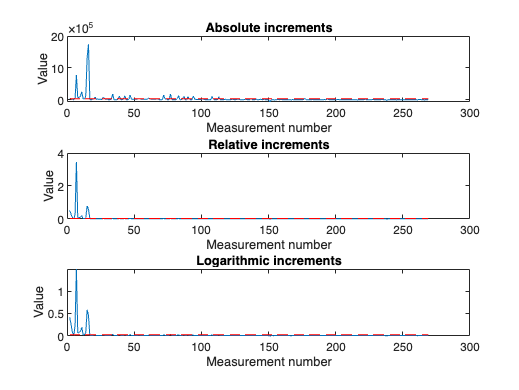

% Calculate the absolute, relative and logarithmic increments
absolute_increments = diff(data);
relative_increments = diff(data) ./ data(1:end-1);
logarithmic_increments = diff(log(data));

% Calculate mean and std
absolute_mean = mean(absolute_increments);
absolute_std = std(absolute_increments);

relative_mean = mean(relative_increments);
relative_std = std(relative_increments);

logarithmic_mean = mean(logarithmic_increments);
logarithmic_std = std(logarithmic_increments);

% Plot the results
figure;

% Absolute increments
subplot(3,1,1);
plot(2:length(data), absolute_increments);    % Start from the second measurement
hold on;
plot([2,length(data)],[absolute_mean,absolute_mean],'r--'); % Plot the mean
jbfill(2:length(data), absolute_mean + absolute_std, absolute_mean - absolute_std, 'r', 'r', true, 0.2);
hold off;
title('Absolute increments');
xlabel('Measurement number');
ylabel('Value');

% Relative increments
subplot(3,1,2);
plot(2:length(data), relative_increments);    % Start from the second measurement
hold on;
plot([2,length(data)],[relative_mean,relative_mean],'r--'); % Plot the mean
jbfill(2:length(data), relative_mean + relative_std, relative_mean - relative_std, 'r', 'r', true, 0.2);
hold off;
title('Relative increments');
xlabel('Measurement number');
ylabel('Value');

% Logarithmic increments
subplot(3,1,3);
plot(2:length(data), logarithmic_increments); % Start from the second measurement
hold on;
plot([2,length(data)],[logarithmic_mean,logarithmic_mean],'r--'); % Plot the mean
jbfill(2:length(data), logarithmic_mean + logarithmic_std, logarithmic_mean - logarithmic_std, 'r', 'r', true, 0.2);
hold off;
title('Logarithmic increments');
xlabel('Measurement number');
ylabel('Value');

Zadanie 2

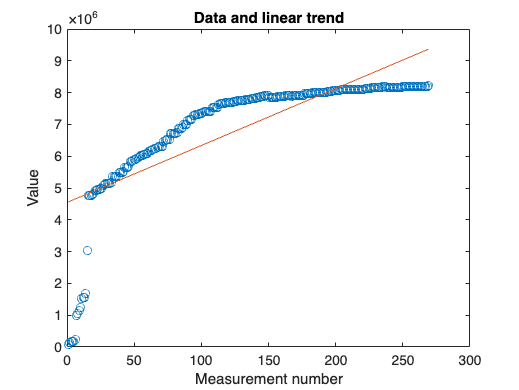

% Get the measurement numbers (assuming constant time intervals between measurements)
measurement_numbers = 1:length(data);

% Perform linear trend approximation
p = polyfit(measurement_numbers,data,1);

% Calculate the approximated data
approx_data = polyval(p,measurement_numbers);

% Calculate the approximation error
error = data - approx_data;

% Display the original data and the linear trend
figure;
plot(measurement_numbers, data, 'o');
hold on;
plot(measurement_numbers, approx_data, '-');
hold off;
title('Data and linear trend');
xlabel('Measurement number');
ylabel('Value');

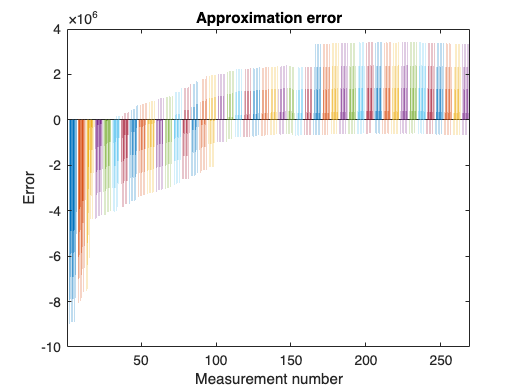


% Display the approximation error
figure;
bar(error)
title('Approximation error');
xlabel('Measurement number');
ylabel('Error');

Zadanie 3

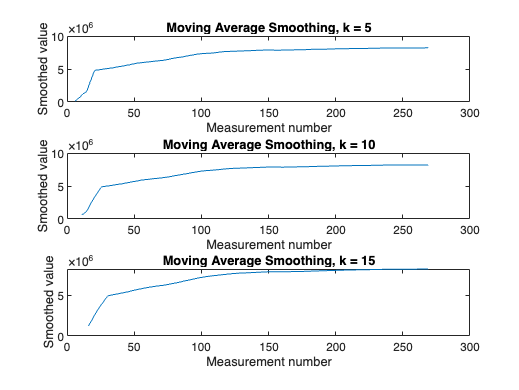

k_values = [5, 10, 15];
lineStyles = ['-', '--', ':'];
colors = ['r', 'g', 'b'];
smoothed_dataset = cell(1,length(k_values));  % Preallocate cell array for storing smoothed data

figure;  % For individual plots

% Apply moving average smoothing for each k
for i = 1:length(k_values)
    k = k_values(i);

    % Preallocate smoothed data array with NaN
    smoothed_data = nan(size(data));

    % Calculate moving average for each data point
    for j = (k+1):length(data)
        smoothed_data(j) = mean(data((j-k):j));
    end

    % Save smoothed_data to cell array
    smoothed_dataset{i} = smoothed_data;

    % Plot the smoothed data
    subplot(length(k_values), 1, i);
    plot(smoothed_data);
    title(['Moving Average Smoothing, k = ' num2str(k)]);
    xlabel('Measurement number');
    ylabel('Smoothed value');
end

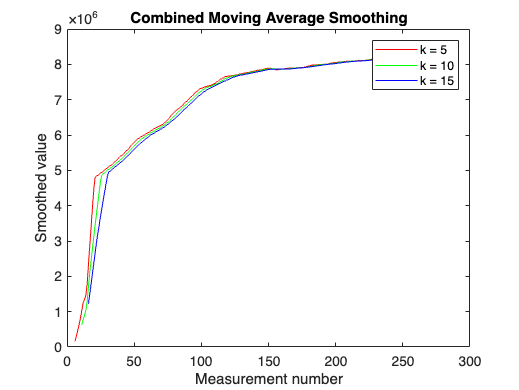


figure;  % For combined plot

for i = 1:length(k_values)
    % Plot the smoothed data on combined graph
    plot(smoothed_dataset{i}, 'LineStyle', lineStyles(i), 'Color', colors(i));
    hold on;
end

hold off;
title('Combined Moving Average Smoothing');
xlabel('Measurement number');
ylabel('Smoothed value');
legend('k = 5', 'k = 10', 'k = 15');

Zadanie 4

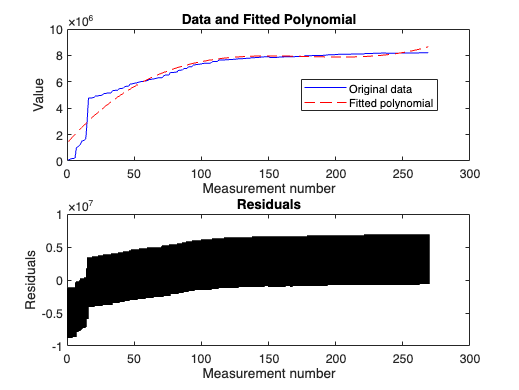

% Fit a polynomial of degree 3 to the data
x = 1:length(data);
p = polyfit(x, data, 3); 
fitted_data = polyval(p, x);

% Calculate the residuals
residuals = data - fitted_data;

% Plot the original data, the fitted data and the residuals
figure;

subplot(2, 1, 1);
plot(x, data, 'b-', x, fitted_data, 'r--');
title('Data and Fitted Polynomial');
legend('Original data', 'Fitted polynomial', 'Location', 'best');
xlabel('Measurement number');
ylabel('Value');

subplot(2, 1, 2);
plot(x, residuals, 'k.');
title('Residuals')
xlabel('Measurement number');
ylabel('Residuals');

Zadanie 5

**Metoda średniej ruchomej (punkt 3)**

- Widzimy, że zwiększanie wartoci $k$ powoduje, że wykres staje się coraz bardziej gładki. Nie są to jednak duże zmiany i prawdopodobnie trzebaby skorzystać z większej wartości parametru $k$, w celu uzyskania lepszego efektu,

- Widać również, że wraz ze wzrostem liczby pomiarów, krzywe coraz bardziej zbiegają do siebie,

**Metoda wielomianowa (punkt 4)**

- Wykres aproksymacji wielomianowej pokazuje, że wielomian 3. stopnia pasuje dobrze do ogólnego trendu danych i jest w stanie z dosyć dobrym przybliżeniem oddać dynamikę wzrostu wartości,

- Widzimy również, że krzywa jest dużo bardziej gładka, co lepiej oddaje ogólny, długoterminowy trend, ale pomija zmienność w niewielkim przedziale czasowym (dla bliskich sobie pomiarów),

- Wykres residuów pokazuje jednak, że wielomian nie modeluje idealnie zmian w zbiorze danych i aproksymowane wartości w zauważalny sposób odbiegają od wartości rzeczywistych,

**Porównanie**

- **Reagowanie na zmiany w danych**: Metoda średniej ruchomej usuwa mniejsze fluktuacje danych oraz szum, ale, im większa wartość $k$, tym bardziej wypłaszczony wykres otrzymamy. Wielomian, z drugiej strony, jeszcze mniej przypomina rzeczywisty wykres zbioru danych, ale dużo lepiej modeluje ogólny trend,

- **Zastosowanie**: Średnia ruchoma nadaje się w większym stopniu do redukcji szumów (generalnego wygładzania) w danych, natomiast wielomian, do badania trendów nieliniowych,